# Flux balance analysis models for iMAT

*Created by Michiel Adriaens (MaCSBio, Maastricht University, 26-06-2020)*

*Adapted by Catarina and Likhitha*

## **Section 0: Intialisation**

% Start the COBRA toolbox. We will additionally turn all warnings of for the time being
cd C:\Users\likhitha\Desktop\cobratoolbox;
warning('off','all');
initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2021
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.30.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu


% There are different solvers available to perform flux balance analysis. Simply stick to the default
changeCobraSolver('glpk','all');

 > The solver compatibility is not tested with MATLAB R2020b.
 > changeCobraSolver: Solver for LP problems has been set to glpk.
 > The solver compatibility is not tested with MATLAB R2020b.
 > changeCobraSolver: Solver for MILP problems has been set to glpk.
 > changeCobraSolver: Solver glpk not supported for problems of type MIQP. Currently used: gurobi 
 > changeCobraSolver: Solver glpk not supported for problems of type NLP. No solver set for this problemtype 
 > changeCobraSolver: Solver glpk not supported for problems of type QP. Currently used: gurobi 



% Load the rat model
cd 'C:\Users\likhitha\Desktop\Project_arrhthymia_scripts\Project_arrhthymia\Data\iRno';
iRnoModel = readCbModel('iRnomodel.mat');

Each model.subSystems{x} has been changed to a character array.



model = iRnoModel;

## Section 1: Perfom flux balance analysis (FBA) simulating aerobic conditions

% Import the gene expression data
cd 'C:\Users\likhitha\Desktop\Project_arrhthymia_scripts\Project_arrhthymia\Data\RNAseqdata';
gxData = readtable('CardioGEM_Rat_geneExpressionData.txt'); 

## Section 2: Simulate ATP production in cancer cells under aerobic conditions

Let's perform the flux balance analysis for an aerobic model for: inhibitor, precursor, scramble inhibitor and scramble precursor

% Load models
cd 'C:\Users\likhitha\Desktop\Project_arrhthymia_scripts\Project_arrhthymia\Data\iRno';
load('EFlux_model_Inhi_likhitha.mat');
load('EFlux_model_Prec_likhitha.mat');
load('EFlux_model_ScrInhi_likhitha.mat');
load('EFlux_model_ScrPrec_likhitha.mat');

% Assign models to correct variable name
% Precursor model
modelaerobiPrec = EFlux_Prec_model;
modelaerobiPrec = changeObjective(modelaerobiPrec, 'RCR11017'); 
modelaerobiPrec = changeRxnBounds(modelaerobiPrec, 'RCR30011', -1000, '1');
FBAaerobicPrec = optimizeCbModel(modelaerobiPrec, 'max');

% Inhibitor model
modelaerobiInhi = EFlux_Inhi_model;
modelaerobiInhi = changeObjective(modelaerobiInhi, 'RCR11017');
modelaerobiInhi = changeRxnBounds(modelaerobiInhi, 'RCR30011', -1000, '1');
FBAaerobicInhi = optimizeCbModel(modelaerobiInhi, 'max');

% Scramble precursor
modelaerobiScrPrec = EFlux_ScrPrec_model;
modelaerobiScrPrec = changeObjective(modelaerobiScrPrec, 'RCR11017'); 
modelaerobiScrPrec = changeRxnBounds(modelaerobiScrPrec, 'RCR30011', -1000, 'l');
FBAaerobicScrPrec = optimizeCbModel(modelaerobiScrPrec, 'max');

% Scramble inhibitor
modelaerobiScrInhi = EFlux_ScrInhi_model;
modelaerobiScrInhi = changeObjective(modelaerobiScrInhi, 'RCR11017'); 
modelaerobiScrInhi = changeRxnBounds(modelaerobiScrInhi, 'RCR30011', -1000, 'l');
FBAaerobicScrInhi = optimizeCbModel(modelaerobiScrInhi, 'max');


## Section 3: Compare results  

Let's visualize the results by focussing on reactions involving lactate in the cytosol.

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

Start_time = '2021_1_16_12_1_12.385'

Biograph object with 7 nodes and 6 edges.


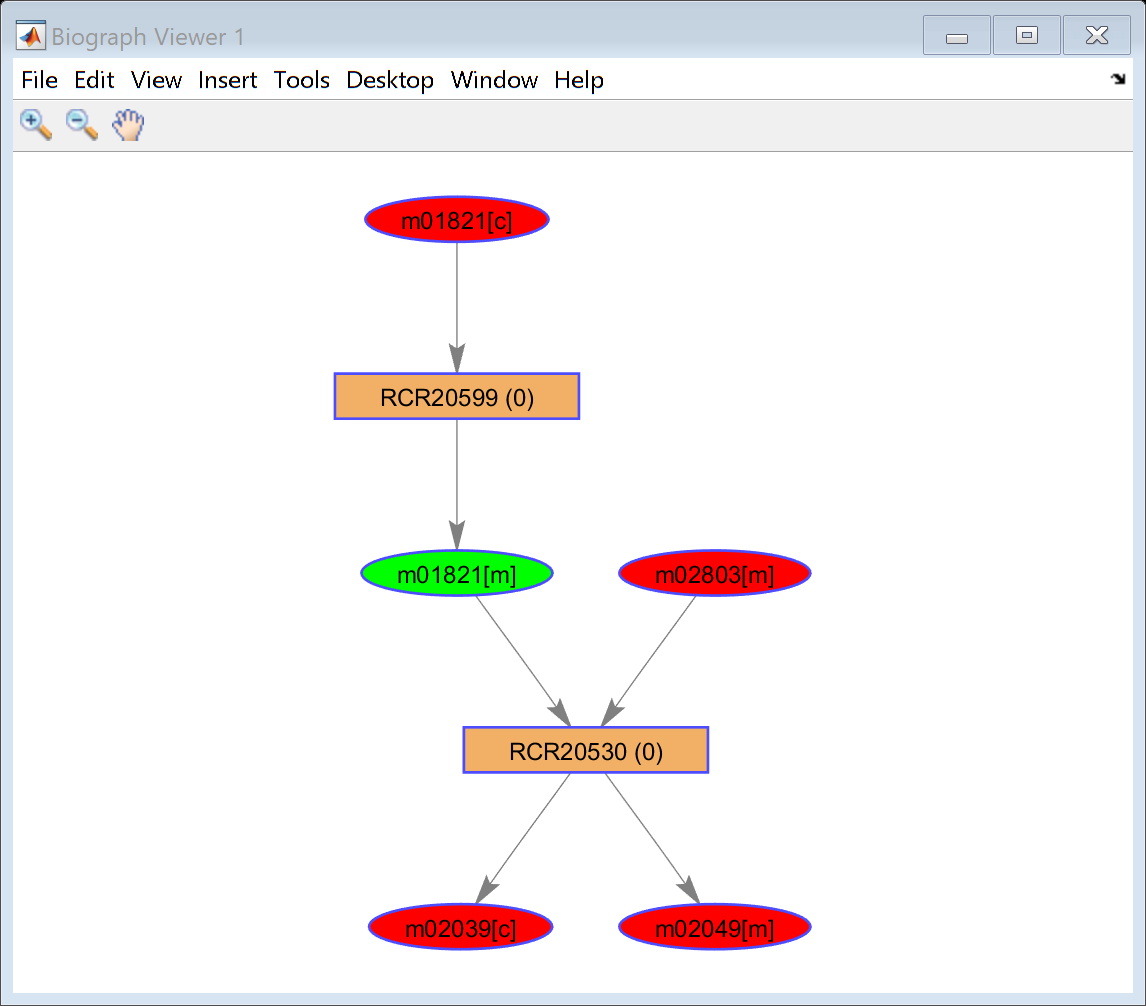

End_time = '2021_1_16_12_1_36.305'

Total_time = '0_0_0_0_0_23.92'

%[reactionNames, rxnPos] = findRxnsFromSubSystem(model, "Electron transport chain")


% Aerobic in Precursor model 
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAaerobicPrec.v);

Start_time = '2021_1_16_12_1_36.413'

Biograph object with 7 nodes and 6 edges.


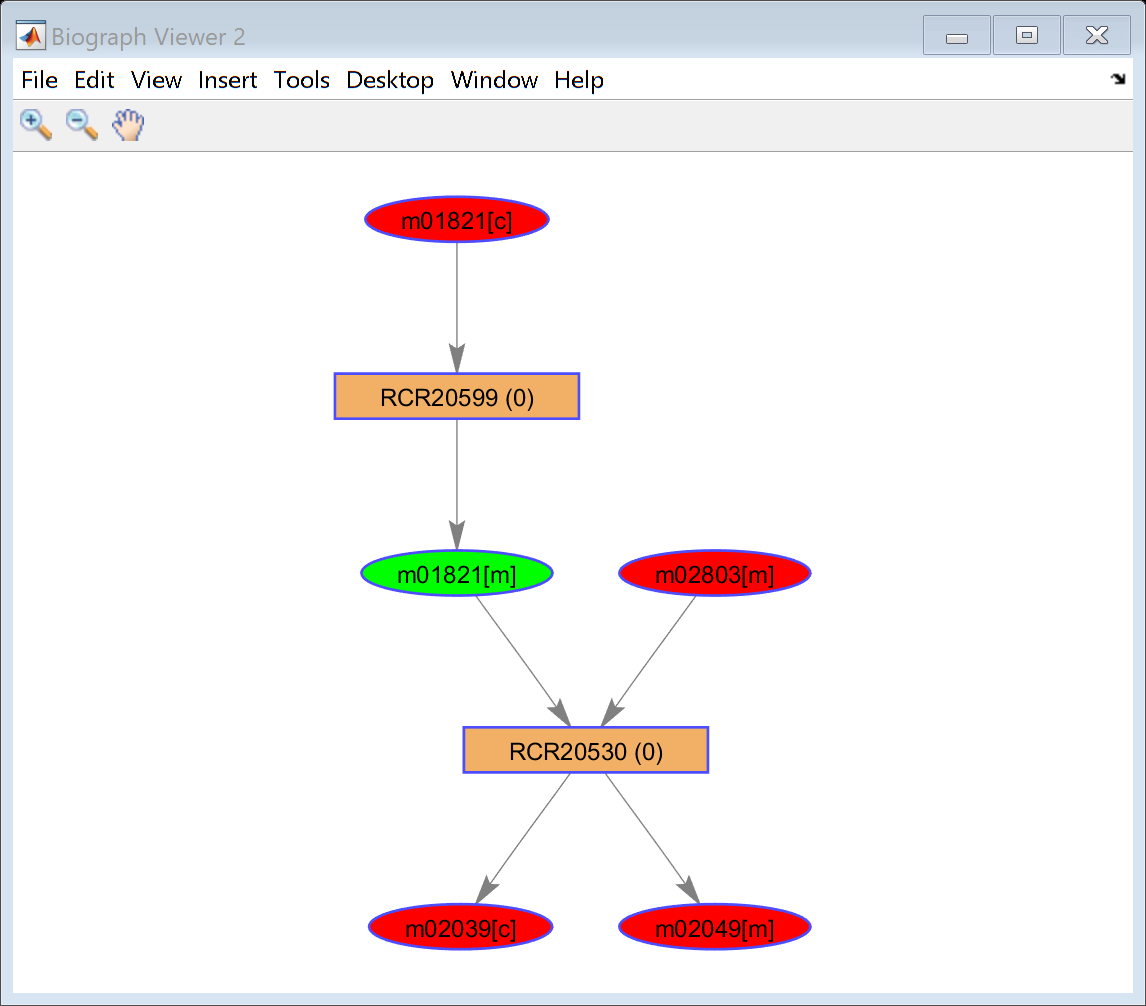

End_time = '2021_1_16_12_1_49.631'

Total_time = '0_0_0_0_0_13.218'


% Aerobic in Inhibitor model
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAaerobicInhi.v);

Start_time = '2021_1_16_12_1_49.736'

Biograph object with 7 nodes and 6 edges.


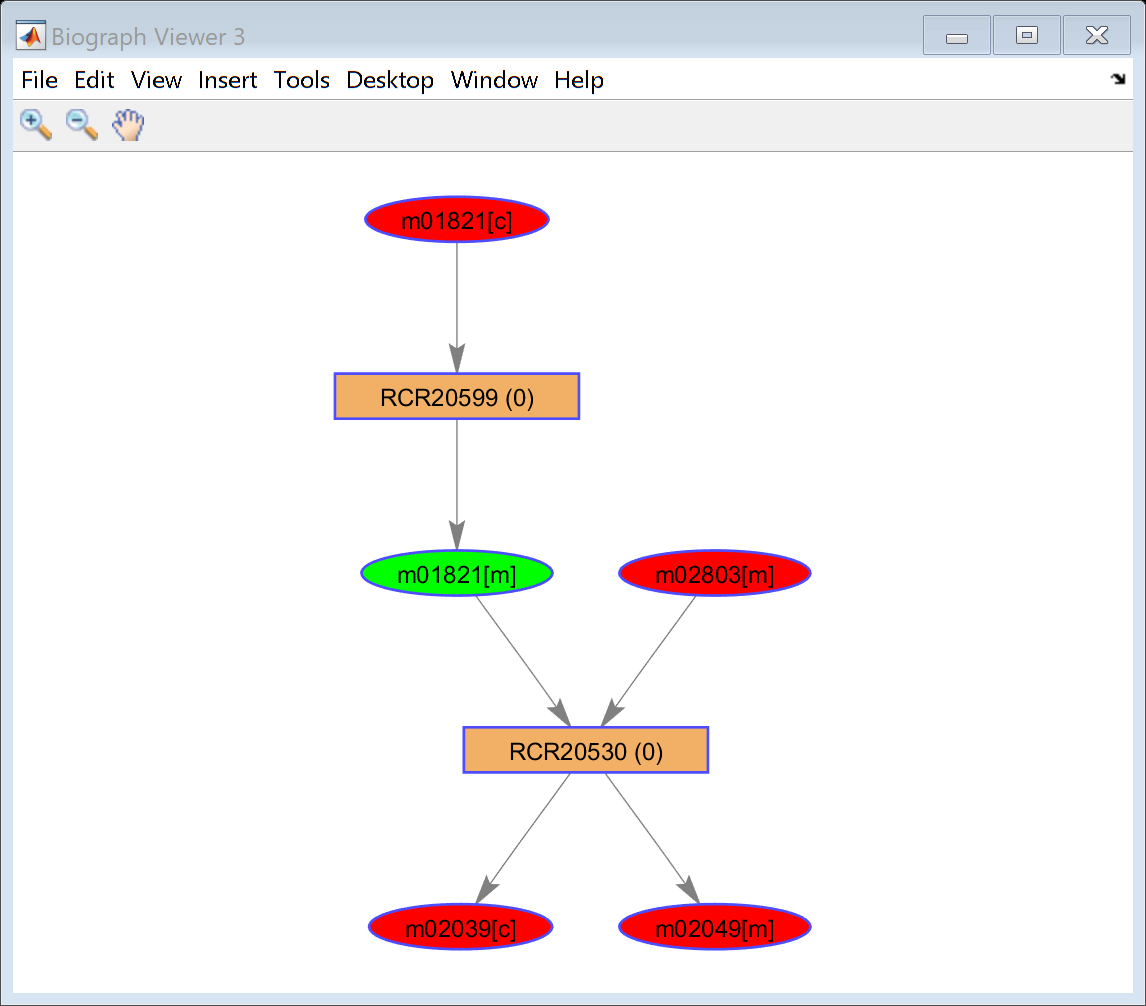

End_time = '2021_1_16_12_2_2.934'

Total_time = '0_0_0_0_1_-46.802'


% Aerobic in Scramble Precursor model
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAaerobicScrPrec.v);

Start_time = '2021_1_16_12_2_2.969'

Biograph object with 7 nodes and 6 edges.


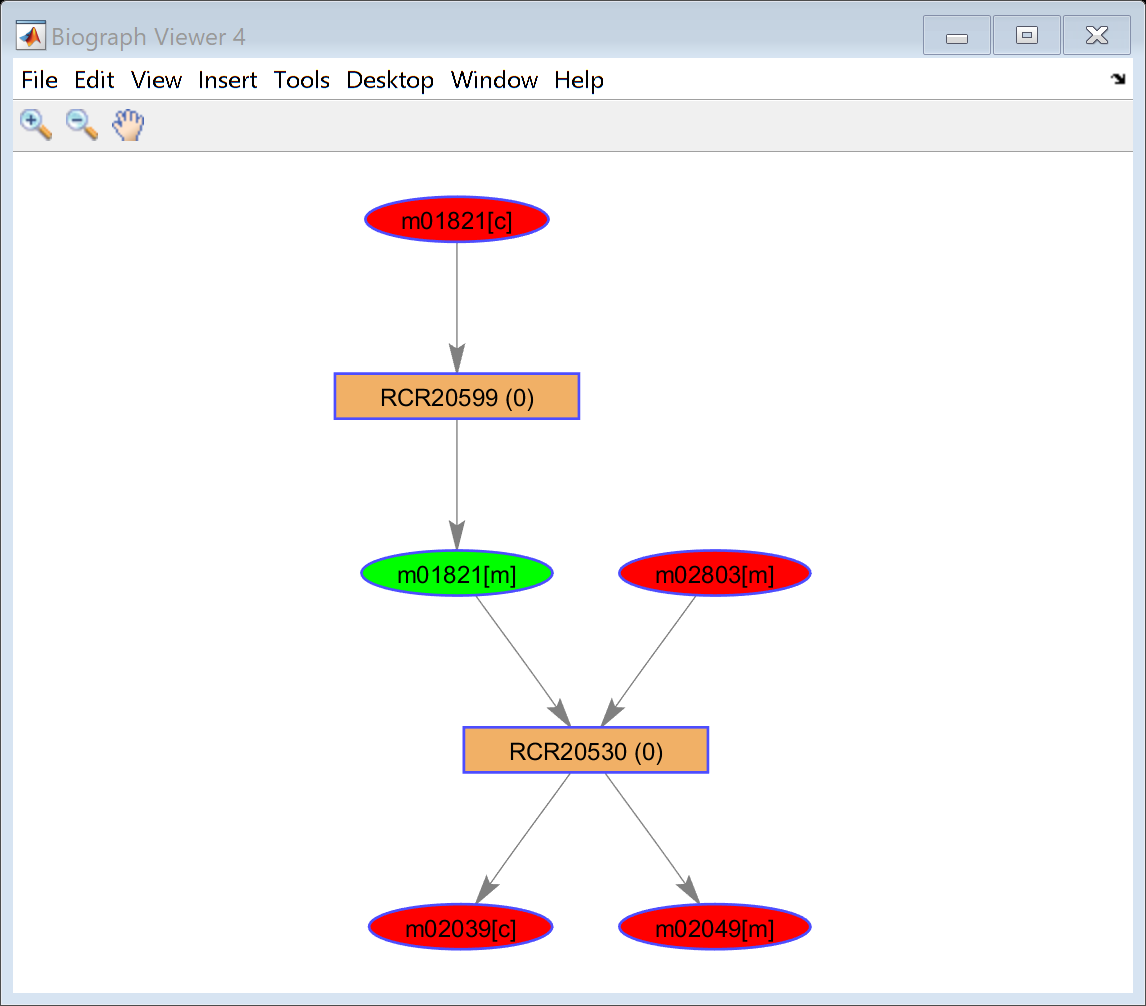

End_time = '2021_1_16_12_2_15.437'

Total_time = '0_0_0_0_0_12.468'


% Aerobic in Scramble Inhibitor model
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAaerobicScrInhi.v);


%draw_by_rxn(model, reactionNames, 'true', 'struc', {''}, {''}, FBAaerobicInhi.v);

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

Start_time = '2021_1_16_12_2_15.513'

Biograph object with 7 nodes and 6 edges.


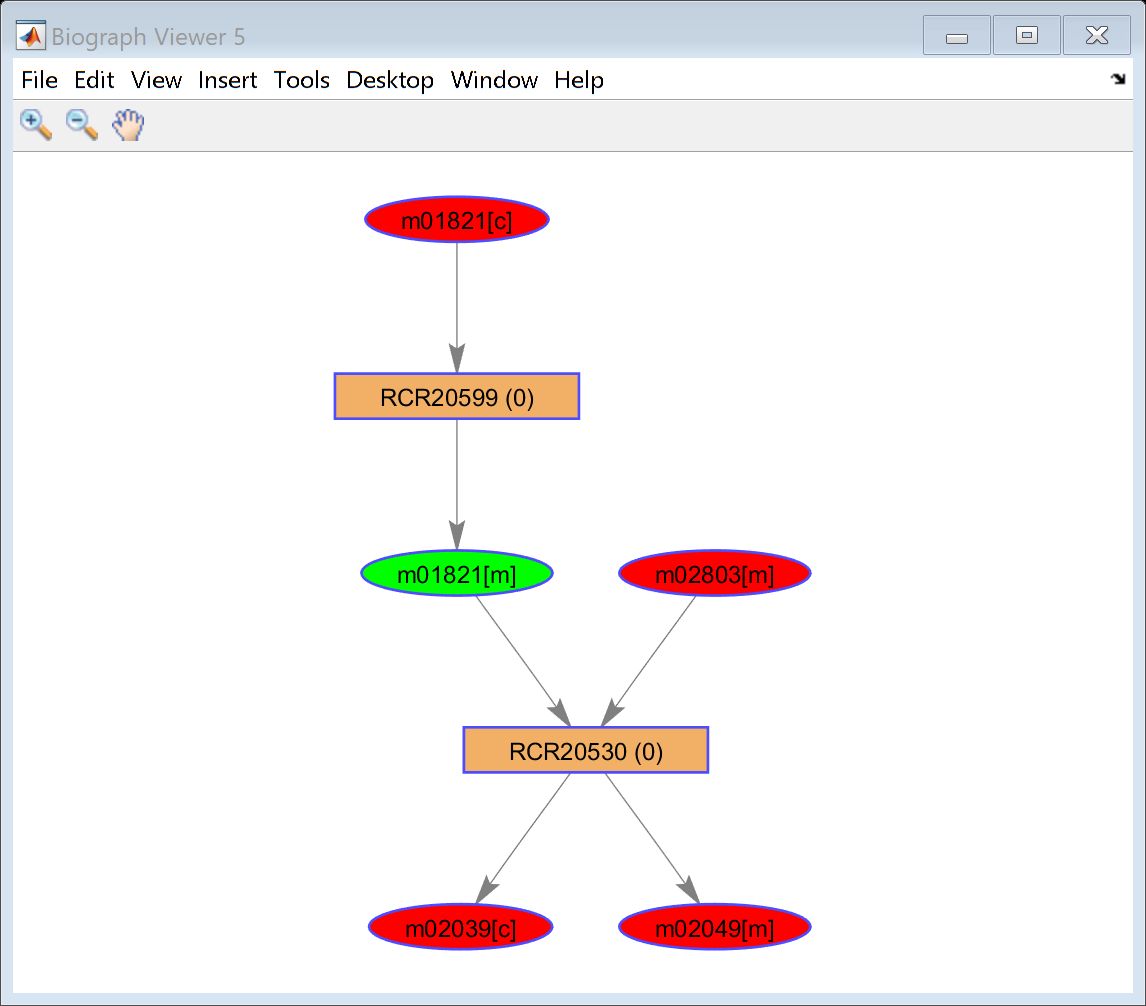

End_time = '2021_1_16_12_2_28.3'

Total_time = '0_0_0_0_0_12.787'

% Focus on difference in flux

% Precursor vs Inhibitor
FBAdiffC_Inhi_Prec.v = round(FBAaerobicInhi.v - FBAaerobicPrec.v);
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAdiffC_Inhi_Prec.v); 

Start_time = '2021_1_16_12_2_28.341'

Biograph object with 7 nodes and 6 edges.


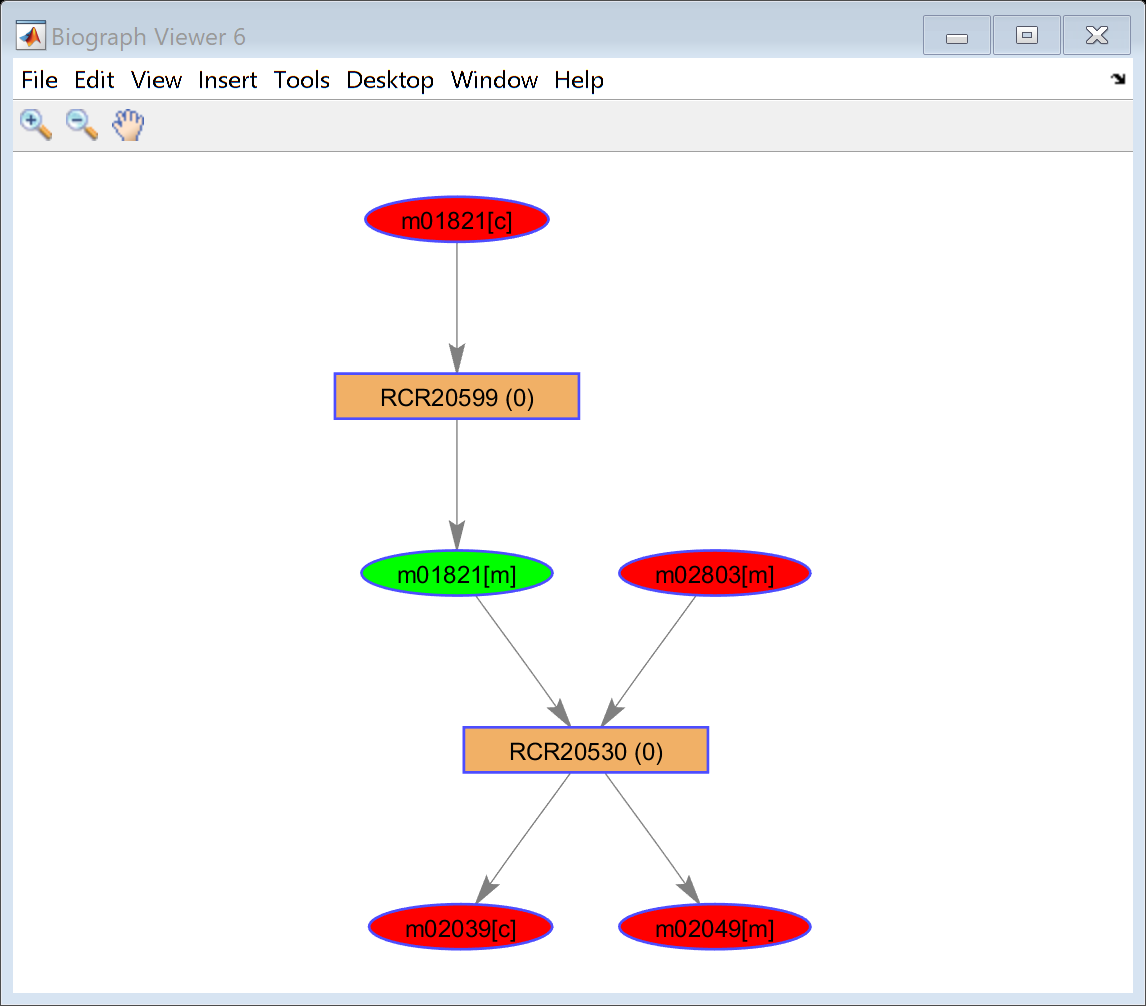

End_time = '2021_1_16_12_2_40.825'

Total_time = '0_0_0_0_0_12.484'


% Inhibitor vs Scramble inhibitor
FBAdiffC_Inhi_ScrInhi.v = round(FBAaerobicInhi.v - FBAaerobicScrInhi.v);
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAdiffC_Inhi_ScrInhi.v); 

Start_time = '2021_1_16_12_2_40.86'

Biograph object with 7 nodes and 6 edges.


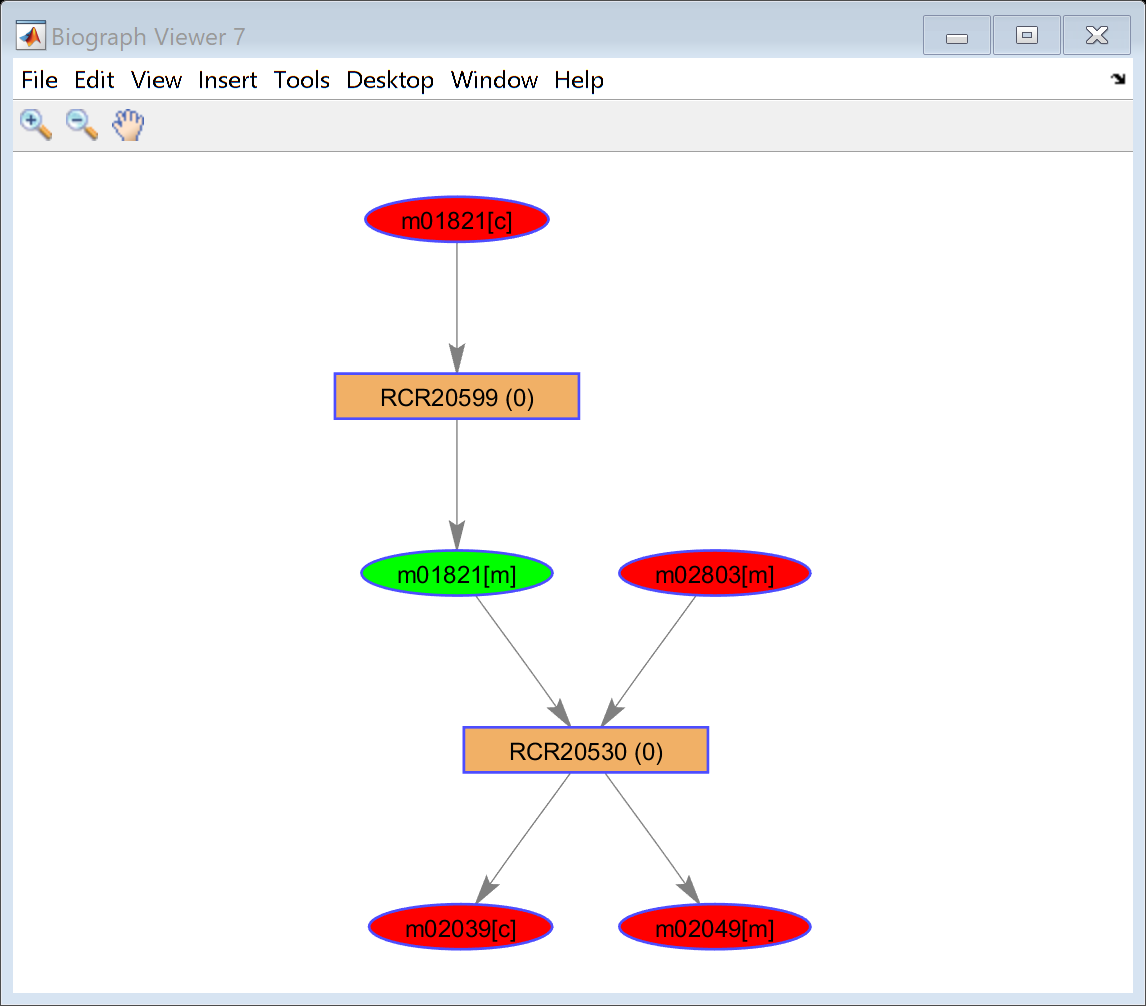

End_time = '2021_1_16_12_2_52.765'

Total_time = '0_0_0_0_0_11.905'


% Precursor vs Scramble Precursor
FBAdiffC_Prec_ScrPrec.v = round(FBAaerobicPrec.v - FBAaerobicScrPrec.v);
draw_by_met(model, {'m01821[m]'}, 'true', 1, 'struc', {''}, FBAdiffC_Prec_ScrPrec.v); 